# Actividad 4.1

Ximena Ortiz Gómez A01735100

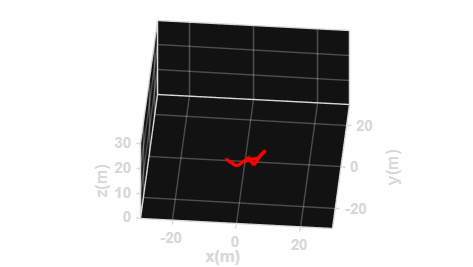

clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tf = 5;             % Tiempo de simulacion (ajustado al dominio)
ts = 0.01;            
t = 0: ts: tf;       
N = length(t);       

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N+1);  
y1 = zeros(1,N+1);  
phi = zeros(1,N+1); 

% Condiciones de la trayectoria específicas
x1(1) = 0;              
y1(1) = 0;              
phi(1) = 0;       

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N+1);  
hy = zeros(1,N+1);  

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N); % velocidad lineal
w = zeros(1,N); % velocidad angular

for k = 1:N
    
    tk = t(k);
    
    dx = 1;
    dy = 4*(tk)*(cos(tk^2));
    
    % Velocidad lineal
    u(k) = sqrt(dx^2+dy^2);
    
    % Velocidad angular
    w(k) = (4*cos(tk^2) - 8*(tk^2)*sin(tk^2)) / (1 + (4*tk*cos(tk^2))^2);    
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    xp1=u(k)*cos(phi(k)); 
    yp1=u(k)*sin(phi(k));
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    %Aplicamos el modelo cinemático diferencial para obtener las
    %velocidades en x, y, phi
    
    phip= w(k);

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([5 40]); % Orientacion de la figura
axis([-30 30 -30 30 0 30]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

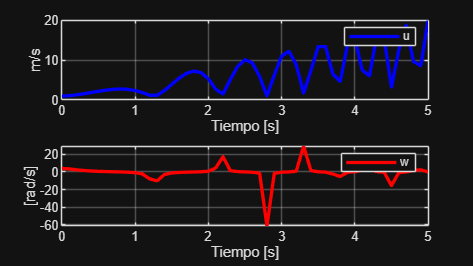


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');

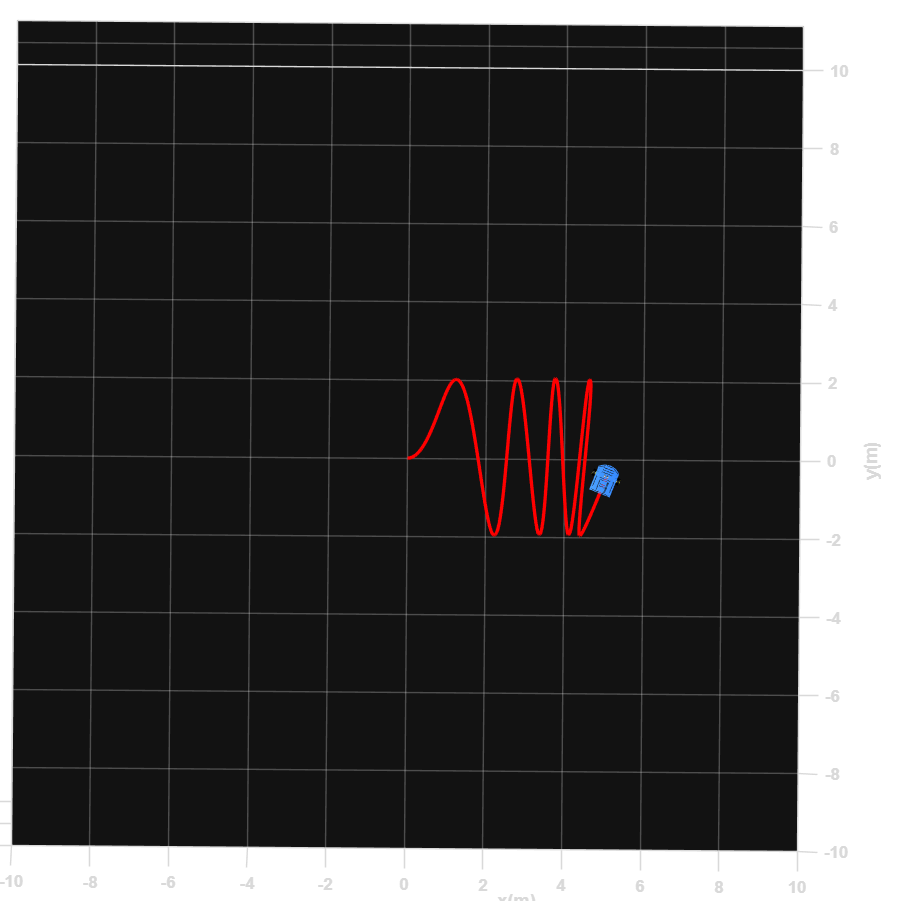

ejercicio 2


clear
close all
clc

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ts = 0.1;

x_up = -3.9:ts:3.9;       % circulo superior
x_down = 3.9:-ts:-3.9;    % ciculo inferior
xtraj = [x_up x_down];

N = length(xtraj);

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros(1,N);
y1 = zeros(1,N);
phi = zeros(1,N);

x1(1) = xtraj(1);
y1(1) = sqrt(16 - xtraj(1)^2);
phi(1) = pi/2;

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1,N);
hy = zeros(1,N);

hx(1) = x1(1);
hy(1) = y1(1);

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%

u = zeros(1,N-1);
w = zeros(1,N-1);

for k = 1:N-1
    
    xk = xtraj(k);
    
    if k <= length(x_up)
        % parte superior
        dx = 1;
        dy = -xk / sqrt(16 - xk^2);
        ddy = -16 / (16 - xk^2)^(3/2);
    else
        % parte inferior
        dx = -1;
        dy = -xk / sqrt(16 - xk^2);
        ddy = 16 / (16 - xk^2)^(3/2);
    end
    
    u(k) = sqrt(dx^2 + dy^2);
    w(k) = (ddy*dx) / (dx^2 + dy^2);
end

%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k = 1:N-1
    
    xp1 = u(k)*cos(phi(k));
    yp1 = u(k)*sin(phi(k));

    x1(k+1) = x1(k) + xp1*ts;
    y1(k+1) = y1(k) + yp1*ts;

    phi(k+1) = phi(k) + w(k)*ts;

    hx(k+1) = x1(k+1);
    hy(k+1) = y1(k+1);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%

scene = figure;
set(scene,'Color','white');
set(gca,'FontWeight','bold');
sizeScreen = get(0,'ScreenSize');
set(scene,'position',sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)');

view([5 40]);
axis([-10 10 -10 10 0 10]);

scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x1(1),y1(1),phi(1),scale); hold on;

H2 = plot3(hx(1),hy(1),0,'r','lineWidth',2);

for k = 1:N
    delete(H1);
    delete(H2);

    H1 = MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2 = plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);

    pause(ts);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% GRAFICAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%

graph = figure;
set(graph,'position',sizeScreen);

subplot(211)
plot(1:N-1,u,'b','LineWidth',2), grid on
xlabel('Muestra')
ylabel('m/s')
legend('u')

subplot(212)
plot(1:N-1,w,'r','LineWidth',2), grid on
xlabel('Muestra')
ylabel('[rad/s]')
legend('w')